# Sottek Hearing Model-based partial loudness comparison

This script compares results from a SHM-based partial loudness with equivalents using the Moore-Glasberg partial loudness.

Note that this script relies on the use of the py2mat function from external package python-for-matlab-development: [https://github.com/Apress/python-for-matlab-development](https://github.com/Apress/python-for-matlab-development) 

## Setup

Last modified: 08/05/2026

% select algorithms directory 
mlabPath = uigetdir("", "Select \refmap-psychoacoustics\src\mlab\ directory");
addpath(genpath(mlabPath))

% setup python
[pyEnvExe, pyEnvPath] = uigetfile('python.exe', "Select the python.exe in the relevant environment directory (.venv\Scripts\)", pwd);
pyEnvExePath = fullfile(pyEnvPath, pyEnvExe);
disp(pyEnvExePath)

C:\Users\m_lot\source\repos\refmap-psychoacoustics\.venv\Scripts\python.exe



addpath(pyEnvPath)

% import pickle module
pickle = py.importlib.import_module('pickle');

% time skips to avoid fades for time-aggregated values
start_skip = 0.5;
end_skip = 0.5;

% get 1/3-octave band frequencies
[fm, ~, ~, fn] = noctf([20, 16e3], 3);

% load colourmap
cmap_viridis = load('cmap_viridis.txt');

% custom colour palette for line plotting
mycolours = [0, 102, 255;
             0, 204, 153;
             255, 0, 102;
             74, 111, 152;
             231, 144, 29; %251, 164, 49;
             204, 153, 255;
             90, 192, 255;
             90, 255, 243;
             255, 110, 212;
             164, 201, 242;
             255, 254, 139;
             255, 243, 255]./255;

% choose output directory for plot files
outputPath = uigetdir("", "Select output directory \03 Experiment\Experiment 1\Analysis\Plots");

if ~isfolder(fullfile(outputPath, "png"))
    mkdir(fullfile(outputPath, "png"))
end
if ~isfolder(fullfile(outputPath, "svg"))
    mkdir(fullfile(outputPath, "svg"))
end
if ~isfolder(fullfile(outputPath, "pdf"))
    mkdir(fullfile(outputPath, "pdf"))
end
addpath(genpath(outputPath))

% choose output directory for data files
outDataPath = uigetdir("", "Select output directory \05 Impact\Articles\JASA_EL_2026_P-SQM\Data");

## File import

% select pickled files (part A only)
[pyFiles, pyPath] = uigetfile({'A*SpecificPartialLoudness.pkl;A*LongTermPartialLoudness.pkl;A*LongTermLoudness.pkl'},...
    "Select .pkl format data files for reading and converting from \03 Experiment\Experiment 1\Analysis\deeuu_loudness\Partial_loudness",...
    'MultiSelect', 'on');
pyFilePaths = fullfile(pyPath, pyFiles);

specPartLoudMGFilePaths = sort(string(pyFilePaths(contains(pyFilePaths, "SpecificPartial")))).';
ltPartLoudMGFilePaths = sort(string(pyFilePaths(contains(pyFilePaths, "LongTermPartial")))).';
longtermLoudMGFilePaths = sort(string(pyFilePaths(contains(pyFilePaths, "LongTermLoud")))).';


% read in the data
fileSkipIdx = 12;
% only select a sample of the specific partial loudness files, for memory
% reasons
clear specPartLoudMG specFiles
fileSelect = 1:fileSkipIdx:length(specPartLoudMGFilePaths);
for file = length(fileSelect):-1:1
    [~, specFiles(file), ~] = fileparts(specPartLoudMGFilePaths(fileSelect(file)));
    fh = py.open(specPartLoudMGFilePaths(fileSelect(file)), 'rb');
    pklData = pickle.load(fh);
    fh.close();
    mData = py2mat(pklData);
    % mData has dimensions [time, masker(1)/target(2), channels, ERBs]
    % select only the target source partial loudness
    % specPartLoudMG has dimensions [time, channels, ERBs, file]
    specPartLoudMG(:, :, :, file) = squeeze(mData(:, 2, :, :));
end
clear mData

% the time-dependent overall partial loudness is binaural-inhibition combined
clear ltPartLoudMG ltPartFiles
fileSelect = 1:fileSkipIdx:length(ltPartLoudMGFilePaths);
for file = length(fileSelect):-1:1
    [~, ltPartFiles(file), ~] = fileparts(ltPartLoudMGFilePaths(fileSelect(file)));
    fh = py.open(ltPartLoudMGFilePaths(fileSelect(file)), 'rb');
    pklData = pickle.load(fh);
    fh.close();
    % mData has dimensions [time, masker(1)/target(2)]
    mData = py2mat(pklData);
    ltPartLoudMG(:, file, 1) = mData(:, 1);
    ltPartLoudMG(:, file, 2) = mData(:, 2);
end
clear mData

% the time-dependent overall loudness is binaural-inhibition combined
clear longtermLoudMG longtermLoudFiles
fileSelect = 1:fileSkipIdx:length(longtermLoudMGFilePaths);
for file = length(fileSelect):-1:1
    [~, longtermLoudFiles(file), ~] = fileparts(longtermLoudMGFilePaths(fileSelect(file)));
    fh = py.open(longtermLoudMGFilePaths(fileSelect(file)), 'rb');
    pklData = pickle.load(fh);
    fh.close();
    % mData has dimensions [time, masker(1)/target(2)]
    mData = py2mat(pklData);
    longtermLoudMG(:, file, 1) = mData(:, 1);
    longtermLoudMG(:, file, 2) = mData(:, 2);
end
clear mData

tMG = (0:1e-3:25 - 1e-3).';  % time vector for Moore-Glasberg
startIdx = 32;  % start index for Moore-Glasberg (avoids negative time)
endInvIdx = 169;  % end index for Moore-Glasberg
cam = 1.75:0.5:39;  % cam ERB index
camF = (10.^(cam./21.366) - 1)./0.004368;  % centre-frequencies per ERB

Next, the Sottek partial and full loudness need to be calculated, using a 'freeFrontal' field option, as this was the default used in the Moore-Glasberg calculations, whereas the Sottek calculations applied to the experiment data used 'diffuse' field setting. To reduce the calculation burden, only those files corresponding with the specFiles are to be selected.

% select wav files
wavString = erase(specFiles, "SpecificPartialLoudness");
uasString = strrep(wavString, "A1", "A");
uasString = strrep(uasString, "A2", "A");
uasString = strrep(uasString, "B2", "B");
ambString = {"A1_CALHEQ_Pa", "A2_CALHEQ_Pa", "B2_CALHEQ_Pa"};

[wavFiles, wavPath] = uigetfile({strjoin(wavString + ".wav", ";"); strjoin(wavString + ".wav", ";")},...
    "Select .wav format data files for reading from \03 Experiment\Experiment 1\Calibration\HATS_EQd",...
    'MultiSelect', 'on');

wavFileNames = string(sort(wavFiles));
wavFilePaths = string(fullfile(wavPath, wavFileNames));


[uasFiles, uasPath] = uigetfile({strjoin(uasString + ".wav", ";"); strjoin(uasString + ".wav", ";")},...
    "Select .wav format data files for reading from \03 Experiment\Experiment 1\Calibration\HATS_EQd",...
    'MultiSelect', 'on');

[~, idx] = ismember(extractAfter(wavFiles, "_"), extractAfter(uasFiles, "_"));
uasFileNames = string(uasFiles(idx));
uasFilePaths = string(fullfile(uasPath, uasFileNames));

[ambFiles, ambPath] = uigetfile({strjoin(ambString + ".wav", ";"); strjoin(ambString + ".wav", ";")},...
    "Select .wav format data files for reading from \03 Experiment\Experiment 1\Calibration\HATS_EQd",...
    'MultiSelect', 'on');

ambFileNames = string(sort(ambFiles));
ambFilePaths = string(fullfile(ambPath, ambFileNames));

% loop to read audio, calculate partial and full Sottek loudness and
% sharpness
for file = length(uasFilePaths):-1:1
    [pUAS, sampleRateIn] = audioread(uasFilePaths(file));
    TonalECMA.data(file) = acousticSHMTonality(pUAS, sampleRateIn, 1, 'freeFrontal', true, false);
    LoudECMA.data(file) = acousticSHMLoudnessFromComponent(TonalECMA.data(file).specTonalLoudness,...
                                                           TonalECMA.data(file).specNoiseLoudness,...
                                                           false, true);
    SharpSHMWid.data(file) = acousticSharpFromSHMLoud(LoudECMA.data(file).specLoudness, 'widmann',...
                                                      false, true);
    TonSharpSHMWid.data(file) = acousticTonalSharpFromSHMTonalLoud(TonalECMA.data(file).specTonalLoudness,...
                                                                   'widmann', false, true);

    TonLoudECMA.data(file).tonLoudTDep = 0.5*sum(TonalECMA.data(file).specTonalLoudness, 2);
    TonLoudECMA.data(file).specTonalLoudness = TonalECMA.data(file).specTonalLoudness;

    wavFile = wavFiles{file};
    ambFilePath = ambFilePaths(strcmp(extractBefore(wavFiles(file), "_"),...
                                      extractBefore(ambFiles, "_")));
    [pAmb, sampleRateIn] = audioread(ambFilePath);
    PartTonalSHM.data(file) = acousticSHMPartialTonality(pUAS, pAmb, sampleRateIn, 1, 'freeFrontal',...
                                                         true, false);
    PartLoudSHM.data(file) = acousticSHMPartialLoudness(pUAS, pAmb, sampleRateIn, 1, 'freeFrontal',...
                                                        true, false, true);

    PartSharpSHMWid.data(file) = acousticSharpFromSHMLoud(PartLoudSHM.data(file).specPartLoudness,...
                                                          'widmann', false, true);

    PartTonLdSHM.data(file).partTonLoudTDep = 0.5*sum(PartTonalSHM.data(file).specPartTonalLoudness, 2);
    PartTonLdSHM.data(file).specPartTonalLoudness = PartTonalSHM.data(file).specPartTonalLoudness;

    PartTonSharpSHMWid.data(file) = acousticTonalSharpFromSHMTonalLoud(PartTonalSHM.data(file).specPartTonalLoudness,...
                                                                       'widmann', false, true);

end

% loop to read ambient audio and calculate full Sottek loudness and
% sharpness
for file = length(ambFilePaths):-1:1
    [pAmb, sampleRateIn] = audioread(ambFilePaths(file));
    AmbTonalECMA.data(file) = acousticSHMTonality(pAmb, sampleRateIn, 1, 'freeFrontal', true, false);
    AmbLoudECMA.data(file) = acousticSHMLoudnessFromComponent(AmbTonalECMA.data(file).specTonalLoudness,...
                                                              AmbTonalECMA.data(file).specNoiseLoudness,...
                                                              false, true);
    AmbSharpSHMWid.data(file) = acousticSharpFromSHMLoud(AmbLoudECMA.data(file).specLoudness, 'widmann', false, true);
    AmbTonLdECMA.data(file).tonLoudTDep = 0.5*sum(AmbTonalECMA.data(file).specTonalLoudness, 2);
    AmbTonLdECMA.data(file).specTonalLoudness = AmbTonalECMA.data(file).specTonalLoudness;
    AmbTonSharpSHMWid.data(file) = acousticTonalSharpFromSHMTonalLoud(AmbTonalECMA.data(file).specTonalLoudness,...
                                                                   'widmann', false, true);
end

PartTonalSHM.files = wavFileNames;
PartLoudSHM.files = wavFileNames;
PartTonLdSHM.files = wavFileNames;
PartSharpSHMWid.files = wavFileNames;
PartTonSharpSHMWid.files = wavFileNames;

TonalECMA.files = uasFileNames;
LoudECMA.files = uasFileNames;
SharpSHMWid.files = uasFileNames;
TonLoudECMA.files = uasFileNames;
TonSharpSHMWid.files = uasFileNames;

AmbTonalECMA.files = ambFileNames;
AmbLoudECMA.files = ambFileNames;
AmbTonLdECMA.files = ambFileNames;
AmbSharpSHMWid.files = ambFileNames;
AmbTonSharpSHMWid.files = ambFileNames;

tSHM = PartLoudSHM.data(1).timeOut;
barkF = PartLoudSHM.data(1).bandCentreFreqs;

## Data saving

% save data
save(fullfile(outDataPath, "PartialLoudnessSHMData.mat"), "TonalECMA", "LoudECMA", "PartTonalSHM",...
     "PartLoudSHM", "AmbTonalECMA", "AmbLoudECMA", '-v7.3')


## Plotting

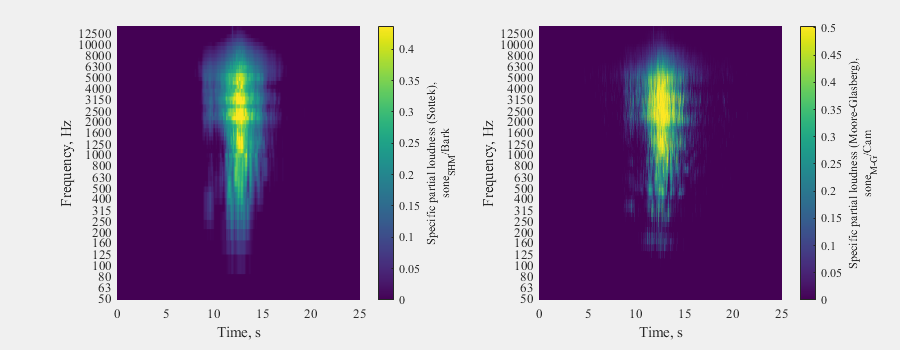

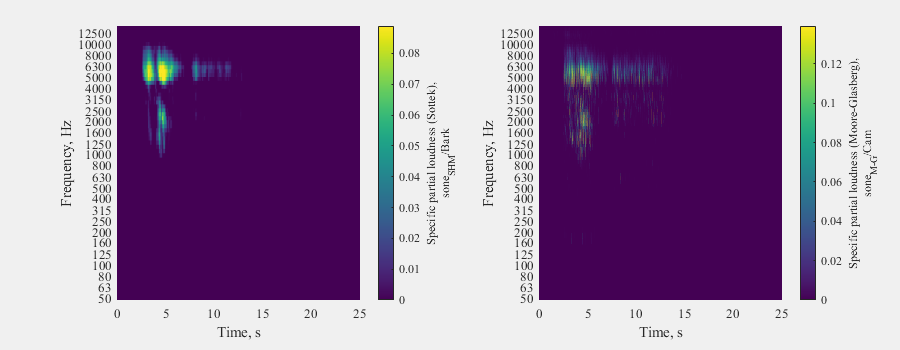

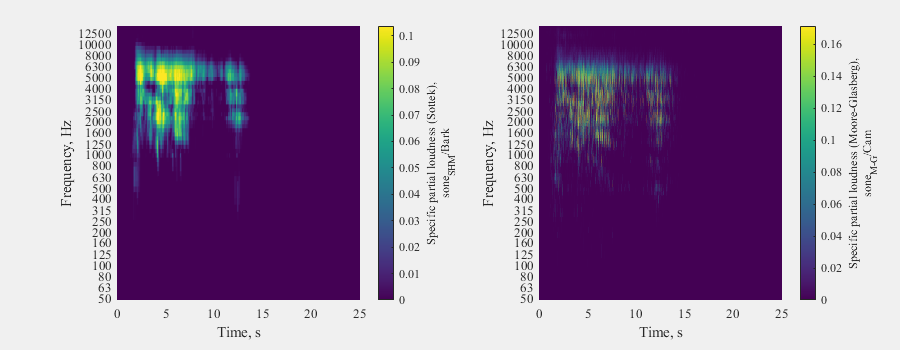

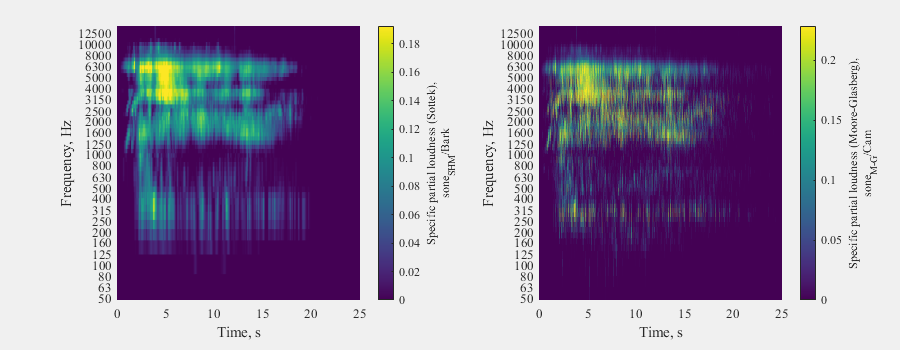

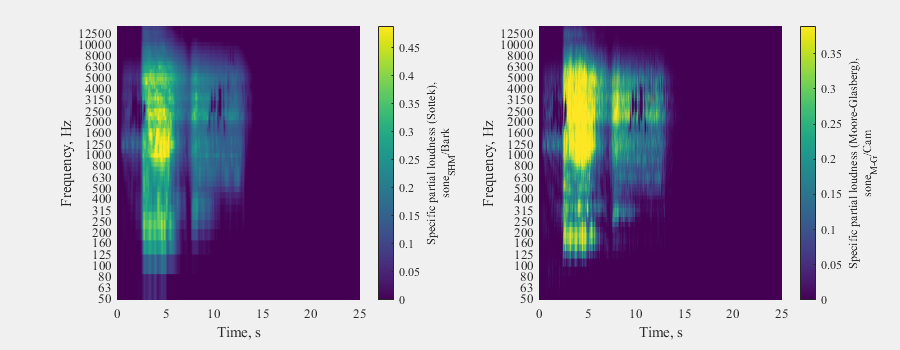

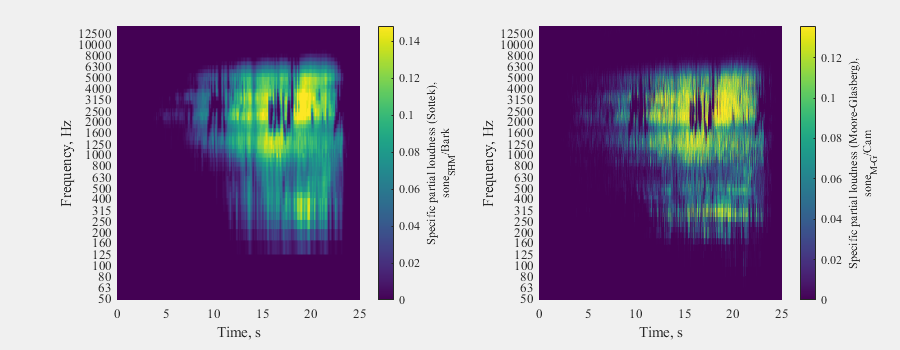

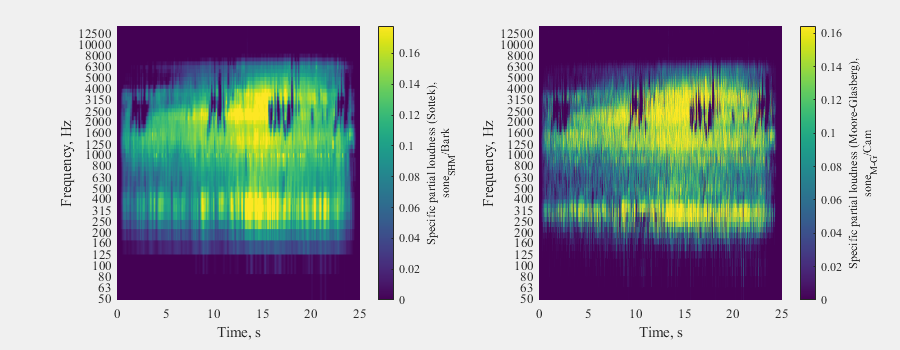

% plot and save specific partial loudness spectrograms

for fileIdx = 1:length(specFiles) 
    fig = specPartLoudCompPlot(tMG, camF, specPartLoudMG(:, :, :, fileIdx),...
                               tSHM, barkF, PartLoudSHM.data(fileIdx).specPartLoudness, 1);
    % save
    filename = "SpecPartLoudComp_" + erase(specFiles(fileIdx), "_PaSpecificPartialLoudness");
    tb = axtoolbar(gca);
    exportgraphics(fig, fullfile(outputPath, "png", filename + ".png"), 'Resolution', 900)
end

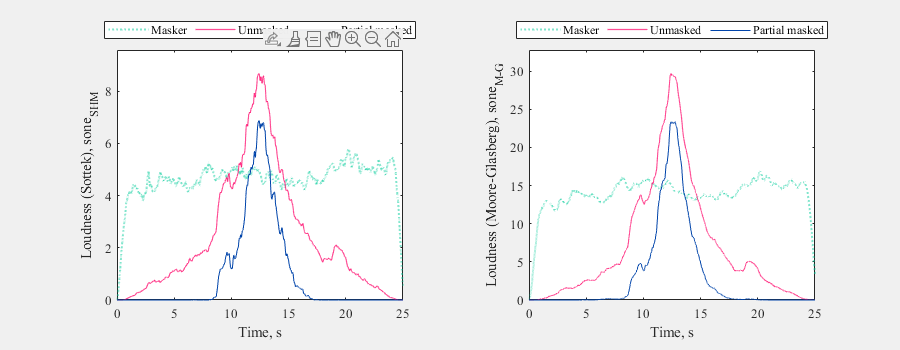

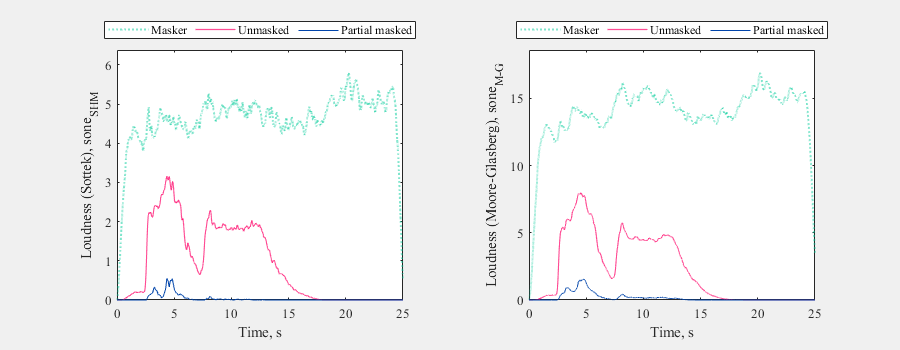

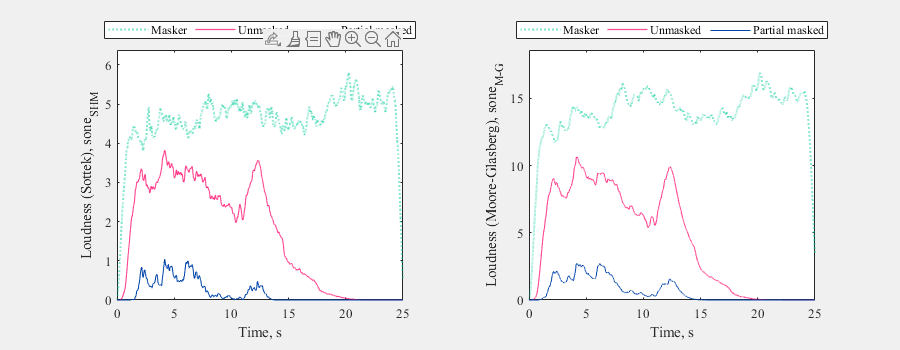

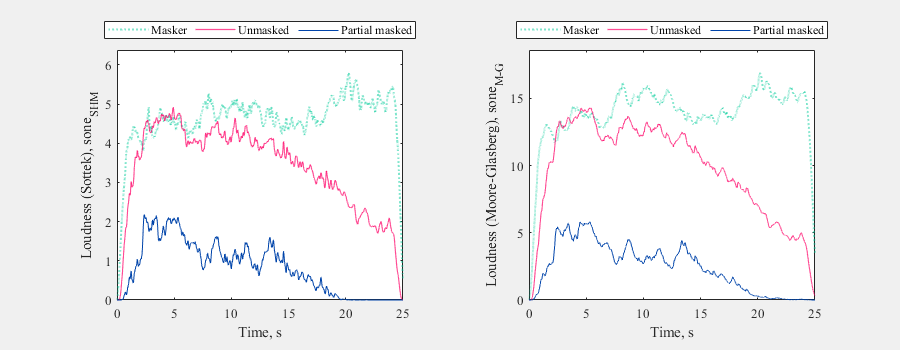

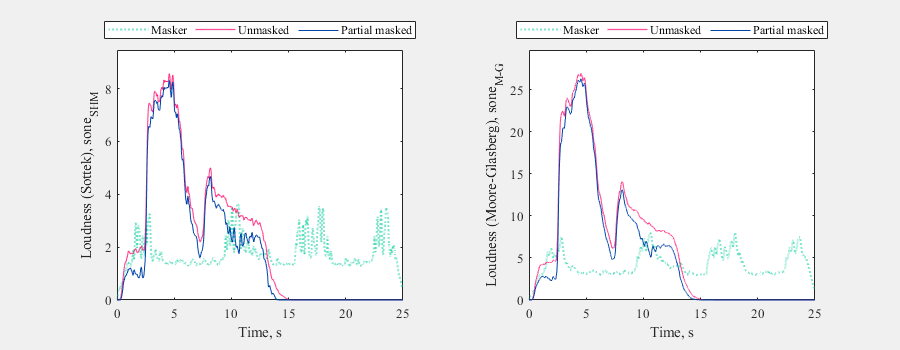

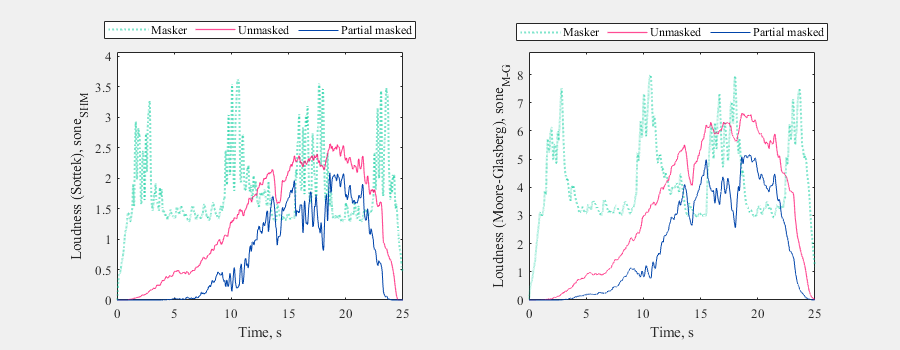

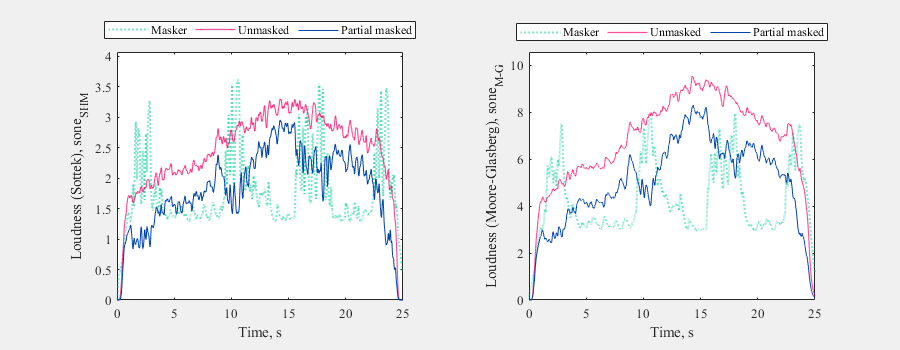

% plot and save time-dependent overall partial loudness along with unmasked
% loudness

for fileIdx = 1:length(ltPartFiles)
    
    ambIdx = strcmp(extractBefore(PartLoudSHM.files(fileIdx), "_"),...
                                  extractBefore(AmbLoudECMA.files, "_"));
    
    fig = partLoudCompPlot(tMG, ltPartLoudMG(:, fileIdx, 2),...
                           longtermLoudMG(:, fileIdx, :),...
                           tSHM, PartLoudSHM.data(fileIdx).partLoudnessTDepBin,...
                           LoudECMA.data(fileIdx).loudnessTDepBin,...
                           AmbLoudECMA.data(ambIdx).loudnessTDepBin);

    % save
    filename = "PartLoudComp_" + erase(ltPartFiles(fileIdx), "_PaLongTermPartialLoudness");
    tb = axtoolbar(gca);
    exportgraphics(fig, fullfile(outputPath, "pdf", filename + ".pdf"), 'ContentType', 'vector')

end

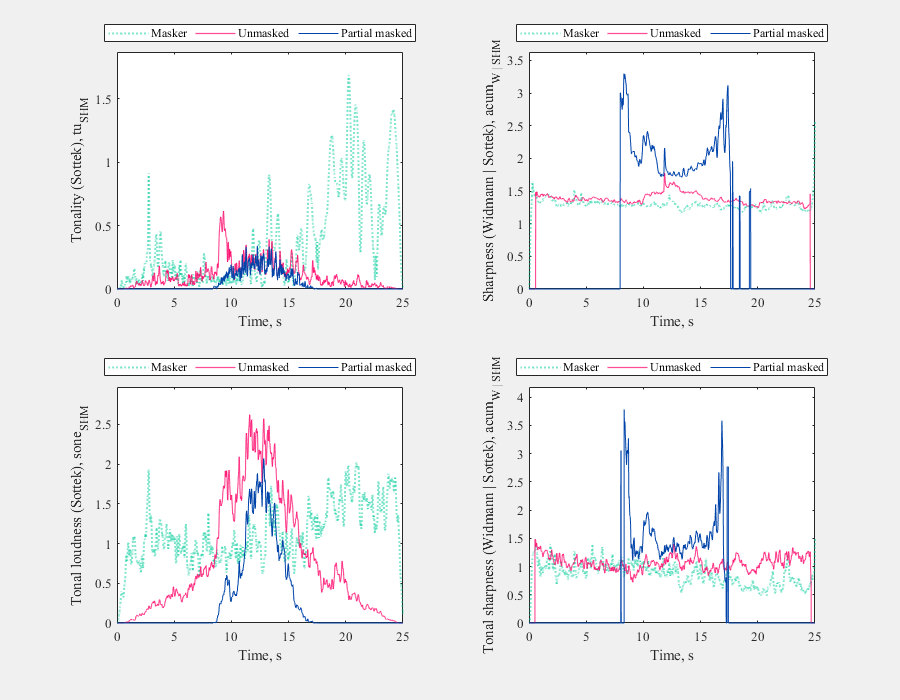

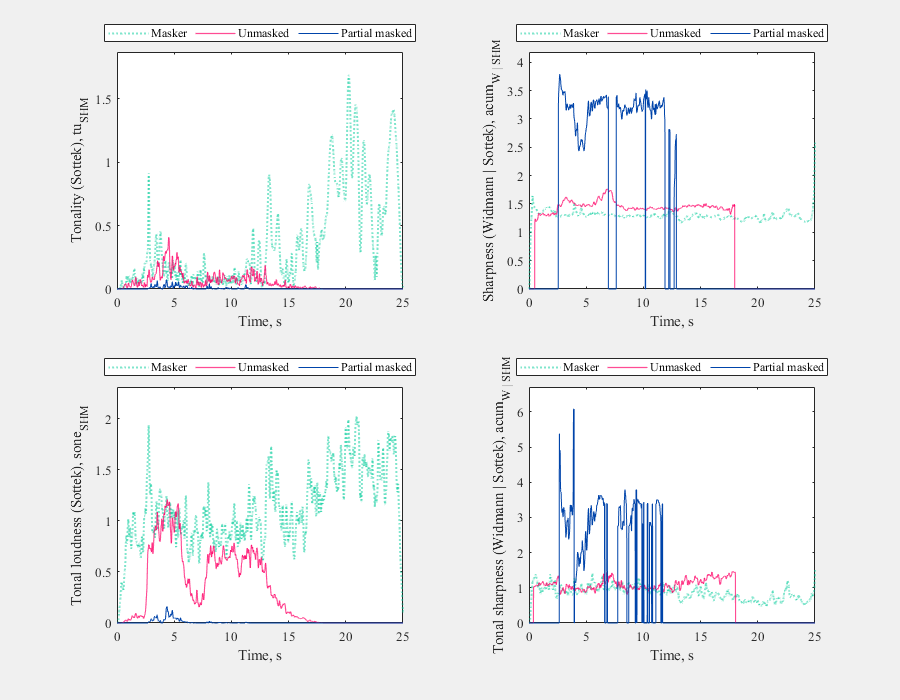

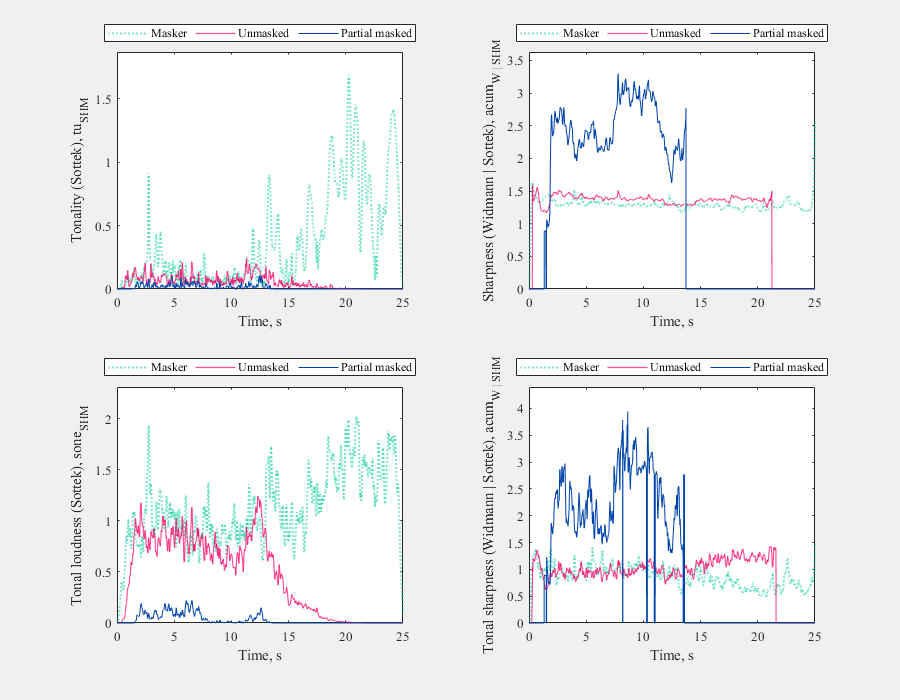

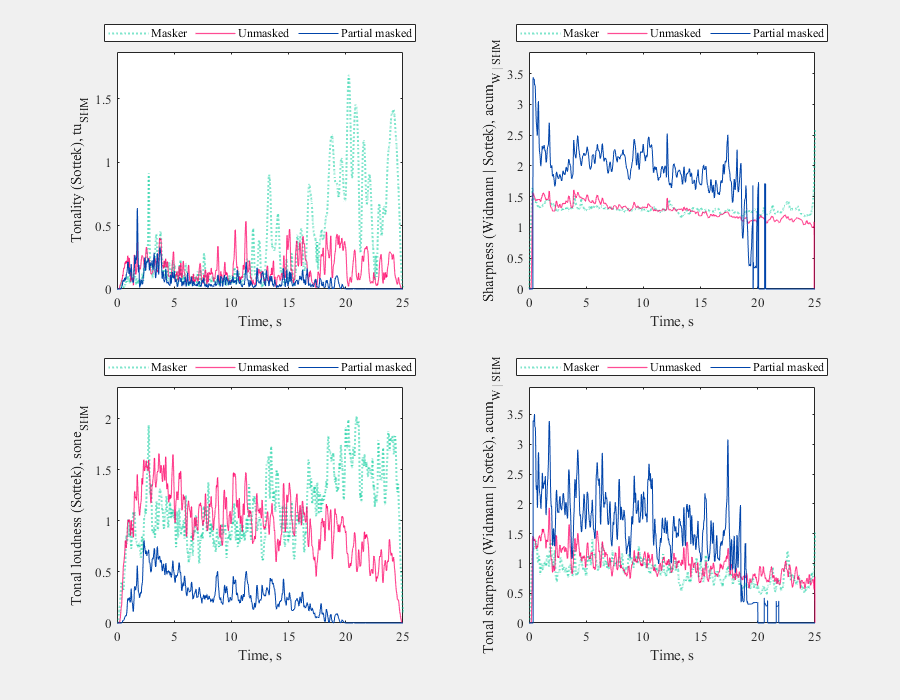

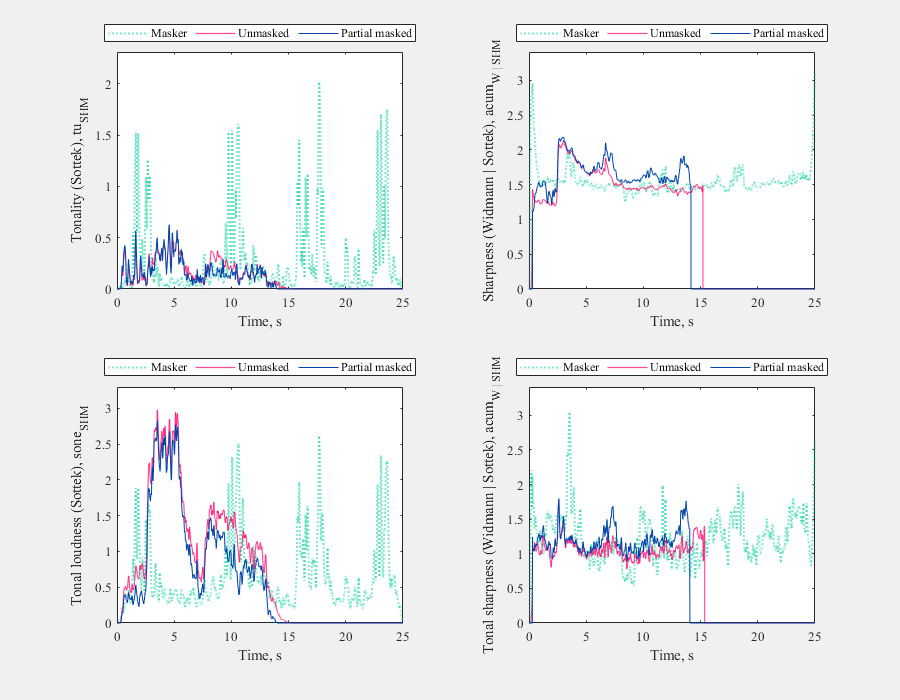

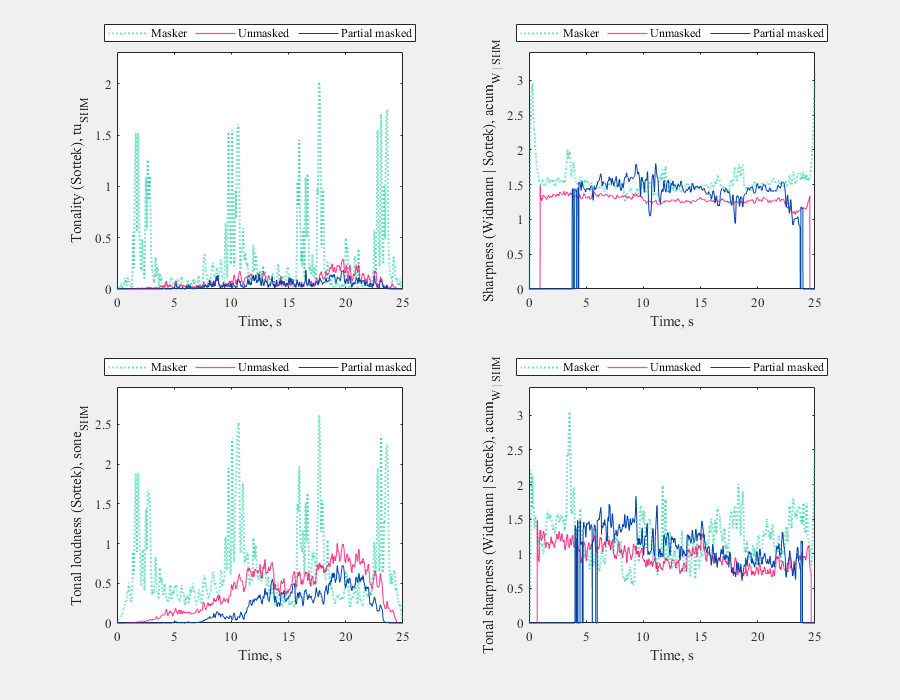

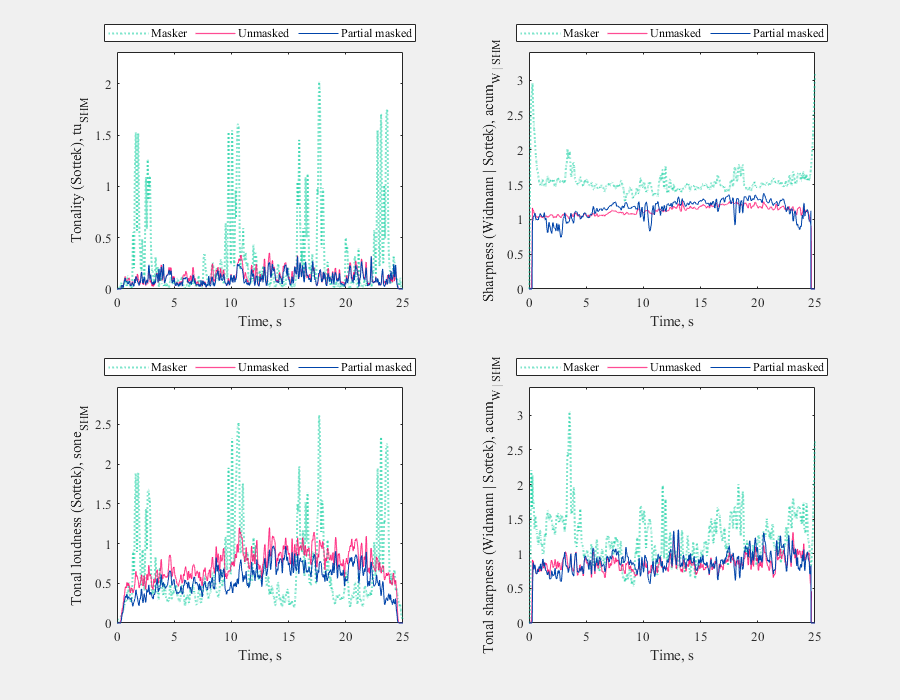

% plot and save partial tonality, tonal loudness, sharpness and tonal
% sharpness

for fileIdx = 1:length(ltPartFiles)
    
    ambIdx = strcmp(extractBefore(PartTonalSHM.files(fileIdx), "_"),...
                                  extractBefore(AmbTonalECMA.files, "_"));
    
    fig = partSQMPlot(tSHM, PartTonalSHM.data(fileIdx).partTonalityTDep(:, 1),...
                      TonalECMA.data(fileIdx).tonalityTDep(:, 1),...
                      AmbTonalECMA.data(ambIdx).tonalityTDep(:, 1),...
                      PartSharpSHMWid.data(fileIdx).sharpnessTDep(:, 1),...
                      SharpSHMWid.data(fileIdx).sharpnessTDep(:, 1),...
                      AmbSharpSHMWid.data(ambIdx).sharpnessTDep(:, 1),...
                      PartTonLdSHM.data(fileIdx).partTonLoudTDep(:, 1),...
                      TonLoudECMA.data(fileIdx).tonLoudTDep(:, 1),...
                      AmbTonLdECMA.data(ambIdx).tonLoudTDep(:, 1),...
                      PartTonSharpSHMWid.data(fileIdx).tonalSharpnessTDep(:, 1),...
                      TonSharpSHMWid.data(fileIdx).tonalSharpnessTDep(:, 1),...
                      AmbTonSharpSHMWid.data(ambIdx).tonalSharpnessTDep(:, 1));

    % save
    filename = "PartSQM_" + erase(ltPartFiles(fileIdx), "_PaLongTermPartialLoudness");
    tb = axtoolbar(gca);
    exportgraphics(fig, fullfile(outputPath, "pdf", filename + ".pdf"), 'ContentType', 'vector')

end

## Plotting functions

Function for plottting comparison of specific partial loudness

function fig = specPartLoudCompPlot(tMG, camF, specPartLoudMG, tSHM, barkF, specPartLoudSHM, channel)

    startIdx = 32;  % start index for Moore-Glasberg (avoids negative time)
    endInvIdx = 169;  % end index for Moore-Glasberg
    cmap_viridis = load('cmap_viridis.txt');
    [~, ~, ~, fn] = noctf([20, 16e3], 3);

    fig = figure;
    set(fig, 'Visible', 'on', 'Position', [100, 100, 900, 350]);
    tiledlayout(fig, 1, 2);
    
    ax1 = nexttile(1);
    specData2 = specPartLoudSHM(:, :, channel);
    surf(tSHM, barkF, specData2.', 'EdgeColor', 'none')
    view(2)
    axis([0, 25, 48, 14600])
    movegui('center')
    cbar1 = colorbar;

    specData2Max = max(specData2, [], 'all');
    if specData2Max == 0
        colormap(ax1, cmap_viridis(1:10, :))
    else
        colormap(ax1, cmap_viridis)
    end
    clim([0, max(ceil(specData2Max*100)/100, 0.001)/1.35]);

    set(ax1, 'YScale', 'log', 'YTick', fn, 'FontName', "Times New Roman")
    xlabel("Time, s")
    ylabel("Frequency, Hz")
    set(get(cbar1, 'label'), 'string', {"Specific partial loudness (Sottek),"; "sone_{SHM}/Bark"});

    ax2 = nexttile(2);
    specData1 = squeeze(specPartLoudMG(startIdx:end - endInvIdx, channel, :));
    surf(tMG, camF, specData1.', 'EdgeColor', 'none')
    view(2)
    axis([0, 25, 48, 14600])
    movegui('center')
    cbar1 = colorbar;

    specData1Max = max(specData1, [], 'all');
    if specData1Max == 0
        colormap(ax2, cmap_viridis(1:10, :))
    else
        colormap(ax2, cmap_viridis)
    end
    clim([0, max(ceil(specData1Max*100)/100, 0.001)/2.8]);
    
    set(ax2, 'YScale', 'log', 'YTick', fn, 'FontName', "Times New Roman")
    xlabel("Time, s")
    ylabel("Frequency, Hz")
    set(get(cbar1, 'label'), 'string', {"Specific partial loudness (Moore-Glasberg),"; "sone_{M-G}/Cam"});
    

end

% function for plotting comparison of time-dependent partial loudness
function fig = partLoudCompPlot(tMG, partLoudMG, loudMG, tSHM, partLoudSHM, loudSHM, ambLoudSHM)

    % custom colour palette for line plotting
    mycolours = [0, 102, 255;
                 0, 204, 153;
                 255, 0, 102;
                 74, 111, 152;
                 231, 144, 29; %251, 164, 49;
                 204, 153, 255;
                 90, 192, 255;
                 90, 255, 243;
                 255, 110, 212;
                 164, 201, 242;
                 255, 254, 139;
                 255, 243, 255]./255;

    startIdx = 32;  % start index for Moore-Glasberg (avoids negative time)
    endInvIdx = 169;  % end index for Moore-Glasberg
    
    fig = figure;
    set(fig, 'Visible', 'on', 'Position', [100, 100, 900, 350]);
    tiledlayout(fig, 1, 2);
    
    ax1 = nexttile(1);
    partLoudData1 = partLoudSHM;
    loudData1 = loudSHM;
    ambLoudData1 = ambLoudSHM;

    plot(tSHM, ambLoudData1, 'color', [mycolours(2, :), 0.5], 'LineStyle', ':', 'LineWidth', 1.5, 'DisplayName', "Masker")
    hold on
    plot(tSHM, loudData1, 'color', [mycolours(3, :), 0.7], 'LineWidth', 0.85, 'DisplayName', "Unmasked")
    plot(tSHM, partLoudData1, 'color', mycolours(1, :)/1.5, 'DisplayName', "Partial masked")
    hold off
    axis([0, 25, 0, 1.1*ceil(max(max(ambLoudData1, loudData1))*10)/10])
    movegui('center')
    
    set(ax1, 'FontName', "Times New Roman")
    xlabel("Time, s")
    ylabel("Loudness (Sottek), sone_{SHM}")
    legend('Location', 'northoutside', 'NumColumns', 3)

    ax2 = nexttile(2);
    partLoudData2 = squeeze(partLoudMG(startIdx:end - endInvIdx, :));
    loudData2 = squeeze(loudMG(startIdx:end - endInvIdx, :, 2));
    ambLoudData2 = squeeze(loudMG(startIdx:end - endInvIdx, :, 1));

    plot(tMG, ambLoudData2, 'color', [mycolours(2, :), 0.5], 'LineStyle', ':', 'LineWidth', 1.5, 'DisplayName', "Masker")
    movegui('center')
    hold on
    plot(tMG, loudData2, 'color', [mycolours(3, :), 0.7], 'LineWidth', 0.85, 'DisplayName', "Unmasked")
    plot(tMG, partLoudData2, 'color', mycolours(1, :)/1.5, 'DisplayName', "Partial masked")
    hold off
    axis([0, 25, 0, 1.1*ceil(max(max(ambLoudData2, loudData2))*10)/10])
    
    set(ax2, 'FontName', "Times New Roman")
    xlabel("Time, s")
    ylabel("Loudness (Moore-Glasberg), sone_{M-G}")
    legend('Location', 'northoutside', 'NumColumns', 3)
    
end


% function for plotting time-dependent partial SQMs
function fig = partSQMPlot(tSHM, partTonalSHM, tonalSHM, ambTonalSHM,...
                           partSharpSHM, sharpSHM, ambSharpSHM,...
                           partTonLdSHM, tonLdSHM, ambTonLdSHM,...
                           partTonSharpSHM, tonSharpSHM, ambTonSharpSHM)

    % custom colour palette for line plotting
    mycolours = [0, 102, 255;
                 0, 204, 153;
                 255, 0, 102;
                 74, 111, 152;
                 231, 144, 29; %251, 164, 49;
                 204, 153, 255;
                 90, 192, 255;
                 90, 255, 243;
                 255, 110, 212;
                 164, 201, 242;
                 255, 254, 139;
                 255, 243, 255]./255;

    fig = figure;
    set(fig, 'Visible', 'on', 'Position', [100, 100, 900, 700]);
    tiledlayout(fig, 2, 2);
    
    ax1 = nexttile(1);
    partSQMData1 = partTonalSHM;
    sqmData1 = tonalSHM;
    ambSQMData1 = ambTonalSHM;

    plot(tSHM, ambSQMData1, 'color', [mycolours(2, :), 0.5], 'LineStyle', ':', 'LineWidth', 1.5, 'DisplayName', "Masker")
    hold on
    plot(tSHM, sqmData1, 'color', [mycolours(3, :), 0.7], 'LineWidth', 0.85, 'DisplayName', "Unmasked")
    plot(tSHM, partSQMData1, 'color', mycolours(1, :)/1.5, 'DisplayName', "Partial masked")
    hold off
    axis([0, 25, 0, 1.1*ceil(max(max(ambSQMData1, sqmData1))*10)/10])
    movegui('center')
    
    set(ax1, 'FontName', "Times New Roman")
    xlabel("Time, s")
    ylabel("Tonality (Sottek), tu_{SHM}")
    legend('Location', 'northoutside', 'NumColumns', 3)

    ax2 = nexttile(2);
    partSQMData2 = partSharpSHM;
    sqmData2 = sharpSHM;
    ambSQMData2 = ambSharpSHM;

    plot(tSHM, ambSQMData2, 'color', [mycolours(2, :), 0.5], 'LineStyle', ':', 'LineWidth', 1.5, 'DisplayName', "Masker")
    hold on
    plot(tSHM, sqmData2, 'color', [mycolours(3, :), 0.7], 'LineWidth', 0.85, 'DisplayName', "Unmasked")
    plot(tSHM, partSQMData2, 'color', mycolours(1, :)/1.5, 'DisplayName', "Partial masked")
    hold off
    axis([0, 25, 0, 1.1*ceil(max(max(ambSQMData2, max(sqmData2, partSQMData2)))*10)/10])
    movegui('center')
    
    set(ax2, 'FontName', "Times New Roman")
    xlabel("Time, s")
    ylabel("Sharpness (Widmann | Sottek), acum_{W | SHM}")
    legend('Location', 'northoutside', 'NumColumns', 3)

    ax3 = nexttile(3);
    partSQMData3 = partTonLdSHM;
    sqmData3 = tonLdSHM;
    ambSQMData3 = ambTonLdSHM;

    plot(tSHM, ambSQMData3, 'color', [mycolours(2, :), 0.5], 'LineStyle', ':', 'LineWidth', 1.5, 'DisplayName', "Masker")
    hold on
    plot(tSHM, sqmData3, 'color', [mycolours(3, :), 0.7], 'LineWidth', 0.85, 'DisplayName', "Unmasked")
    plot(tSHM, partSQMData3, 'color', mycolours(1, :)/1.5, 'DisplayName', "Partial masked")
    hold off
    axis([0, 25, 0, 1.1*ceil(max(max(ambSQMData3, sqmData3))*10)/10])
    movegui('center')
    
    set(ax3, 'FontName', "Times New Roman")
    xlabel("Time, s")
    ylabel("Tonal loudness (Sottek), sone_{SHM}")
    legend('Location', 'northoutside', 'NumColumns', 3)

    ax4 = nexttile(4);
    partSQMData4 = partTonSharpSHM;
    sqmData4 = tonSharpSHM;
    ambSQMData4 = ambTonSharpSHM;

    plot(tSHM, ambSQMData4, 'color', [mycolours(2, :), 0.5], 'LineStyle', ':', 'LineWidth', 1.5, 'DisplayName', "Masker")
    hold on
    plot(tSHM, sqmData4, 'color', [mycolours(3, :), 0.7], 'LineWidth', 0.85, 'DisplayName', "Unmasked")
    plot(tSHM, partSQMData4, 'color', mycolours(1, :)/1.5, 'DisplayName', "Partial masked")
    hold off
    axis([0, 25, 0, 1.1*ceil(max(max(ambSQMData4, max(sqmData4, partSQMData4)))*10)/10])
    movegui('center')
    
    set(ax4, 'FontName', "Times New Roman")
    xlabel("Time, s")
    ylabel("Tonal sharpness (Widmann | Sottek), acum_{W | SHM}")
    legend('Location', 'northoutside', 'NumColumns', 3)

    
end